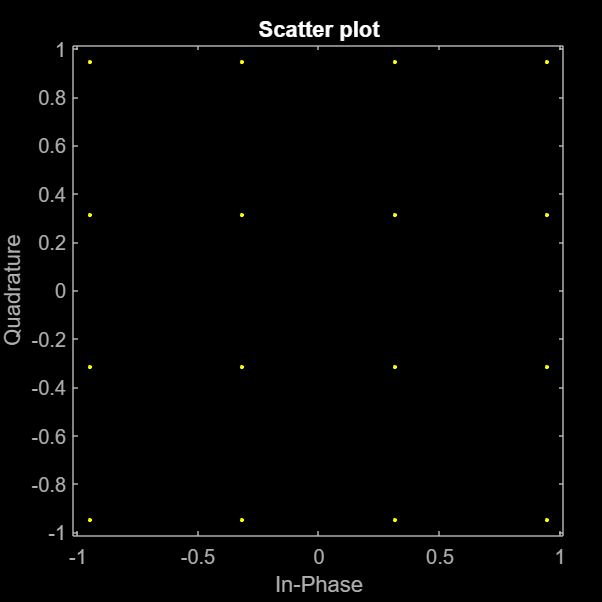

%Periodogram_radar
%DFT-Precoded OFDM or DFT-spread-OFDM (DFT-s-OFDM)

c = 3e8; % speed of light

% OFDM system parameters (802.11p)
subcarrierSpacing = 78.125e3; % subcarrier spacing 78.125 KHz (same to Wifi6 and 802.11p)
%MaxNumber of tones = (BW in MHz) ÷ (0.078125 MHz)

Tu = 1/subcarrierSpacing; % the "useful" symbol period
G = 1/8; % the guard interval fraction
Tg = G*Tu; % the guard interval time
To = Tu + Tg; % the OFDM symbol duration (period)
fC = 5.9e9; % 5.9GHz
N = 64; % 4 pilot tones, other for data
numPilotTones = 4; % no. pilot tones used

% QAM
modOrder = 16; % modulation order being used
modType = "QAM"; % type of modulation being used
% https://www.mathworks.com/help/comm/ref/qammod.html
% modulates input signal x by using QAM with the specified modulation order M
modulated = qammod((0:modOrder-1), modOrder, 'UnitAveragePower', true); %create a data vector containing each of the possible symbols
% Display the modulated signal constellation using the scatterplot function.
scatterplot(modulated)


%minimize PAPR in UL via DFT
% PAPR: peak power is proportional to IFFT length (L)
% DFT (length k) before IFFT, k<L

M = 256; % the no. of symbols in a frame
mapType = "interleave"; % type of mapping that is taking place
L = 4*N; % size of IFFT block used on Tx side 256

Ftx = zeros(N, M); % the transmit frame 64x256

% loading the transmit frame with symbols from the signal set
for row = 1:N %for all tones
    Ftx(row, :) = randsample(modulated, M, true); %length M
end

FtxCopy = Ftx; % making a copy before we apply FFT to Ftx
Ftx = fft(Ftx); % taking the FFT before performing the symbol mapping stage

% Now we need to map the o/p of DFT block to the i/p of IDFT block:
excess = (L/2-1) - N; % the no. of excess i/p pins on IDFT block
symbolMapOp = zeros(L, M); % 256x256 output of symbol mapper - this goes into IDFT

switch (mapType)
    case "interleave"
        % The variable below is the amount of zeros that we will insert between
        % each symbol on the input pins of the IDFT block:
        interPadLength = floor(excess/(N-1));
        % Below we are mapping each of the (N) outputs of the DFT block to
        % the (L) inputs of the IDFT block
        for i = 1:N
            symbolMapOp(1+1+(i-1)*(interPadLength+1), :) = Ftx(i, :);
        end
    case "local"
        % insertIndex is the index where the first symbol from the output
        % of the Tx-side DFT block should be mapped to in the Tx-side IDFT
        % block. In "localised" mapping, the data (Ftx in our case) is 
        % usually padded above and below by zeros:
        insertIndex = (excess + 1)/2 + 1 + 1;
        symbolMapOp(insertIndex:insertIndex+N-1, :) = Ftx;
    otherwise
        disp("ERROR: check the value of 'mapType' at the top of the script.")
        return
end

% Parameters of targets:
distances = [30 34];
velocities = [60 50];
rcs = [10 15];
% The attenuation factor:
% = sqrt((c*targetRCS)/((4*pi)^3*(d^4)*(fC^2)));
alpha = sqrt((c.*rcs)./((4*pi)^3*(distances.^4)*(fC^2)));

numTargets = length(distances);
%Doppler shift
fD = 2*fC*(velocities)/c;
%time delay
tau = 2*(distances)/c;

l = 0:M-1; %tones M
k = 0:L-1; %ifft size L

dopplerTerm = zeros(numTargets, M);
delayTerm = zeros(numTargets, L);

for row = 1:numTargets %in frequency, similar to channel effect
    dopplerTerm(row, :) = exp(1i*2*pi*l*To*fD(row));
    delayTerm(row, :) = exp(-1i*2*pi*k*tau(row)*subcarrierSpacing);
end

Frx = zeros(L, M); %receiver frame 256x256
noise = wgn(L, M, -140, 'complex');

%form the receive frame by modelling the effect of the channel
% and the target on the transmited frame:
for column = 1:M
    for target = 1:numTargets
        Frx(:, column) = Frx(:, column) + alpha(target)*symbolMapOp(:, column)*dopplerTerm(target, column).*delayTerm(target, :).';
    end
end

% The OFDM beacon knows what frame was sent, and hence we can divide the
% received frame by the transmitted one:
F = Frx./symbolMapOp;

% And now we can remove the rows with "Inf" values, which were caused
% by dividing by "0"s in the transmit frame (Ftx)
F(1, :) = 0;
F(L/2 + 1, :) = 0;
F(isnan(abs(F))) = 0;

% The size of the extended periodogram:
Nper = 5*L;
Mper = 5*M;

% The subcarrier spacing should be at least one order of magnitude
% bigger than the largest occurring Doppler shift - hence a value of 1/10 
% for the quantity D...
D = 1/10;

% Defining our search range below:
Nmax = G*Nper; % The row at beyond which we should stop looking for peaks
Mmax = round(D*Mper); % The column beyond which we should stop searching for peaks

% Complex periodogram calculation:
Cper = F; % The complex periodogram is calculated using F...

Cper = Cper.';
Cper = fft(Cper, Mper); % FFT of each row (length of FFT is Mper)
Cper = Cper.';
Cper = ifft(Cper, Nper); % IFFT of each column...
numCols = size(Cper, 2);
Cper = Cper(1:Nmax, :); % cropping
Cper = flip(fftshift(Cper, 2), 1);
Cper = Cper(:, (numCols/2)-Mmax:(numCols/2)+Mmax-1); % cropping

% Periodogram calculation:
Per = 1/(Nmax*(2*Mmax + 1))*(abs(Cper).^2);
% Getting the maximum value from the cropped periodogram:
maxPer = max(Per(:));
% The x and y axis are reversed in the periodogram...
[y, x] = ind2sub(size(Per), find(Per == maxPer));

% The estimated position indexes
m_hat = x - (size(Per, 2)/2 + 1);
n_hat = size(Per, 1) - y + 1;

tau_hat = (n_hat - 1)/(Nper*subcarrierSpacing);% The time dela

distance = (n_hat - 1)*c/(2*subcarrierSpacing*Nper);
velocity = (m_hat - 1)*c/(2*fC*To*Mper);

% The index vectors below can be used to find the distance
% and velocity values, which can be used to label the axes...
mIndexes = (1:size(Per, 2)) - (size(Per, 2)/2 + 1);
nIdexes = (1:size(Per, 1));

% Working out the corresponding distance and velocity vector
% associated with each (n, m) index...
distancesVec = (nIdexes - 1)*c/(2*subcarrierSpacing*Nper);
velocitiesVec = round((mIndexes - 1)*c/(2*fC*To*Mper));

distances

distances =     30    34


velocities

velocities =     60    50



% Creating label variables to use with the heatmap object below:
distanceLabels = string(distancesVec);
distanceLabels(~(ceil(distancesVec) == floor(distancesVec))) = "";
velocityLabels = string(velocitiesVec);
meanDiff = round(mean(diff(velocitiesVec)));
velocitiesVec2 = min(velocitiesVec):meanDiff:min(velocitiesVec) + meanDiff*(length(velocitiesVec)-1);
velocityLabels2 = string(velocitiesVec2);
velocityLabels(~(mod(velocitiesVec, 5) == 0)) = "";
velocityLabels = replace(velocityLabels, "550", "");
velocityLabels2(~(mod(velocitiesVec2, 5) == 0)) = "";

h = heatmap(velocitiesVec, flip(distancesVec), Per, 'Colormap', jet(300));
s = struct(h);

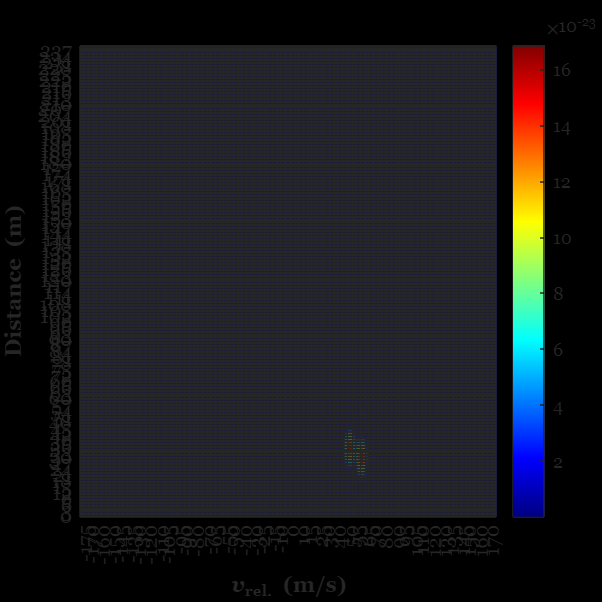

s.XAxis.TickLabelRotation = 90;
h.YDisplayLabels = flip(distanceLabels);
h.XDisplayLabels = velocityLabels;
set(gca,'Fontname', 'Georgia');
xlabel('\fontname{Georgia}\bf\itv\rm\bf_{rel.} (m/s)');
ylabel('\fontname{Georgia}\bfDistance (m)');